# Cvičení 6 - B2M31AEDA

## Nahrání dat

**Důležité! **V dnešním cvičení naleznete na Moodle ke stažení dva data sety, `data.csv` a `large_dataset.csv`. Předtím, než přistoupíte k načítání dat do Matlabu (klasicky pomocí funkce `readtable`, viz předešlá cvičení), musíte se rozhodnout, který z těchto dvou datasetu použijete.

## ČTĚTE POZORNĚ ZADÁNÍ!!! 😊

large = true;
if large
    T = readtable('large_dataset.csv','ReadVariableNames',true);
else
    T = readtable('data.csv','ReadVariableNames',true);
end

## 1. Estimace potřebné velikosti vzorku

V této části potřebujete program GPower, volně ke stažení pomocí odkazu v zadání. V zadání se také nachází na konci PDF návod na použití.

Pečlivě čtěte zadání, v této části je možné udělat mnoho malých chyb.

- Nejprve si musíte přečíst otázky na konci zadání (v 3. části), na které budete chtít odpovídat.

- Vyberte statistický test, který na jejich zodpovězení použijete. Správně vyhodnoťte normalitu parametrů (viz zadání).

- Vypočítejte pomocí GPower potřebnou velikost vzorku.

**Otázky:**

- Zapište jaké testy použijete pro zodpovězení otázek z části 3.

- Zapište vypočtené minimální potřebné velikosti vzorku pro jednotlivé testy.

- Zaznamenejte jaké datasety jste se rozhodli použít případně jaké parametry jste se rozhodli vyřadit.

#### Vaše odpovědi a výsledky:

**Zapište jaké testy použijete pro zodpovězení otázek z části 3.**

- otázka Ttest2 + korekce

- otázka korelace + korekce

**Zapište vypočtené minimální potřebné velikosti vzorku pro jednotlivé testy.**

1) 

DDKG = 454

DDKR = 20

stdF0 = 384

jitter = 54

2)

Speech = 36

**Zaznamenejte jaké datasety jste se rozhodli použít případně jaké parametry jste se rozhodli vyřadit.**

Large dataset, vyřazuji DDKGa stdF0

## 2. Vizualizace vybraných dat

Skupiny dat vybrané pro zodpovězení otázek z části 3 vhodně vizualizujte. Použijte zobrazení, na kterém bude nejvíce zřetelný efekt mezi skupinami.

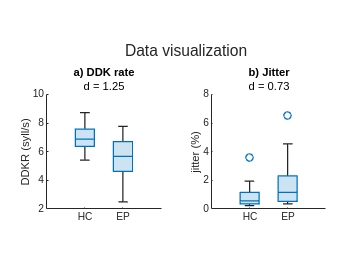

% Váš kód pro vizualizaci
function d = cohenD(data1, data2)
    n1 = length(data1); n2 = length(data2);
    s1 = std(data1); s2 = std(data2);
    mu1 = mean(data1); mu2 = mean(data2);

    sP = sqrt(((n1 - 1)*(s1^2) + (n2 - 1)*(s2^2))/(n1+n2+2));
    d = (mu1 - mu2)/sP;
end

tl = tiledlayout("flow");
title(tl, "Data visualization")
ax1 = nexttile;
data1 = T{T.group == "HC", "DDKR"};
data2 = T{T.group == "EP", "DDKR"};
if length(data1) > length(data2)
    data2 = [data2; NaN(length(data1) - length(data2), 1)];
elseif length(data1) < length(data2)
    data1 = [data1; NaN(length(data2) - length(data1), 1)];
end

boxchart([data1, data2])
set(gca, 'XTickLabel', {'HC', 'EP'})
title('a) DDK rate'); ylabel('DDKR (syll/s)')
pbaspect(ax1,[1 1 1]);
d1 = cohenD(T{T.group == "HC", "DDKR"}, T{T.group == "EP", "DDKR"});
subtitle(sprintf("d = %.2f", d1))

ax2=nexttile;
data1 = T{T.group == "HC", "jitter"};
data2 = T{T.group == "EP", "jitter"};
if length(data1) > length(data2)
    data2 = [data2; NaN(length(data1) - length(data2), 1)];

elseif length(data1) < length(data2)
    data1 = [data1; NaN(length(data2) - length(data1), 1)];
end
boxchart([data1 data2])
set(gca, 'XTickLabel', {'HC', 'EP'})
title('b) Jitter'); ylabel('jitter (%)')
pbaspect(ax2,[1 1 1]);
d2 = cohenD(T{T.group == "EP", "jitter"}, T{T.group == "HC", "jitter"});
subtitle(sprintf("d = %.2f", d2))

- Slovně zhodnoťte (vizuálním odhadem), zdali je mezi skupinami vidět nějaký efekt skupin (size effect).

- Vypočítejte velikost efektu skupin pomocí Cohenova d a podle jeho velikosti uveďte, jak velký tento efekt je.

#### Vaše odpovědi a výsledky:

U obou je vidět rozdíl, u DDKR výraznější. Toto potvrzuje i Cohenovo d.

DDKR má velmi vysoký sizeeffect, Jitter ho má významný

## 3. Úloha

K následujícím otázkám navrhněte hypotézy, vyberte vhodné testy, nastavte hladinu statistické významnosti korigovanou pro ošetření chyby I. typu a korektně reportujte svoje výsledky do Moodle. **Mějte na paměti, že oproti předešlým cvičením, zde budete mít jednu hypotézu na každou z otázek, a pod touto hypotézou provedete určitý počet testů. **

- *Vykazuje skupina EP rozdíly oproti skupině zdravých lidí z pohledu nějakého z příznaků DDKG, DDKR, stdF0 nebo jitter?*

- *Odráží příznak DDKG, DDKR, stdF0 nebo jitter motorické zhodnocení pomocí skóre NNIPPS? Vyberte si ***jednu položku*** z dotazníku NNIPPS, pro kterou vztah vyšetříte.*

% Váš kód
% 1
no_test = 2;
alpha = 0.05;
bonferroni_alpha = alpha / no_test;

h = zeros(1,no_test);
p = zeros(1,no_test);
ci = zeros(1,no_test);
stats = struct('tstat', {}, 'df', {}, 'sd', {});

r1 = [T{T.group == "HC", "DDKR"}, T{T.group == "HC", "jitter"}];
r2 = [T{T.group == "EP", "DDKR"}, T{T.group == "EP", "jitter"}];

for i=1:no_test
    [h(i), p(i), ci(i,:), stats(i)] = ttest2(r1(:,i), r2(:,i));
end

h = p < bonferroni_alpha;

% 2
no_test = 2;
alpha = 0.05;
bonferroni_alpha = alpha / no_test;

rho = zeros(1,no_test);
p = zeros(1,no_test);

r1 = [T{T.group == "EP", "DDKR"}, T{T.group == "EP", "jitter"}];
r2 = T{T.group == "EP", "Speech"};

for i=1:no_test
    [rho(i), p(i)] = corr(r1(:,i), r2);
end
h = p < bonferroni_alpha;

### Hypotézy, reporty:

H0: skupina EP nevykazuje rozdíl oproti skupině HC z příznaků (DDKR, Jitter)

alpha = 0.05

t_DDKR(51) = 4.3752, p = .0000601

t_jitter(51) = -2.5539, p = .0137

Po korekci zamítáme obě H0 ve prospěch alternativních hypotéz.

====

H0: korelace skore NNIPPS a parametru (DDKR, Jitter) je nulová.

alpha = 0.05

r_DDKR(26) = -0.6501, p = .00018, 1-β = .955

r_jitter(26) = .4188, p = 0.0266, 1-β = .507

Po korekci zamítáme první test a nezamítáme druhý. Tedy DDKR odráží položku Speech testu NNIPPS.